# Time evolution for the linear Schrodinger equation on a lollipop graph

Evolves the linear Schrodinger equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

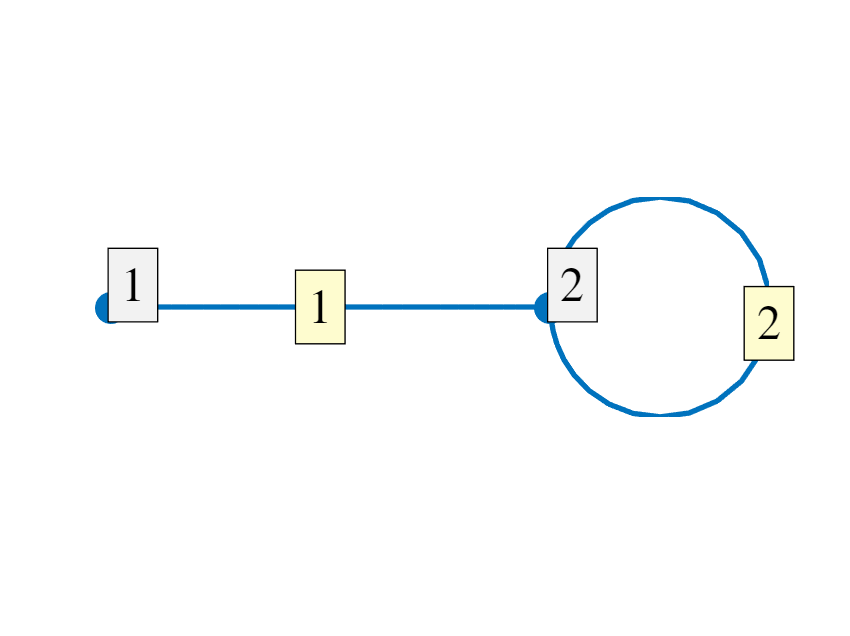

Phi = quantumGraphFromTemplate('multibell','discretization','Chebyshev','nX',32,'nbells',1);
Phi.plot('layout')

## Define the function

We define the linear Schrodinger equation on Phi.

A = Phi.laplacianMatrix;  % The second spatial derivative operator
f = @(t,z) 1i * A*z;

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used an eigenfunction of the stationary problem as an initial condtion.

[evec,eval] = Phi.eigs(8);
lambda1 = eval(3);
lambda2 = eval(5);
u0 = lambda1.*evec(:,3)+lambda2.*evec(:,5);
deltat = 1e-05;
tend = .5;
% [u,t] = Phi.timeEvolveDAE(f,u0,deltat,tend,8);
[t,u] = Phi.timeEvolveDH(f,u0,tend);

## Plotting the solution

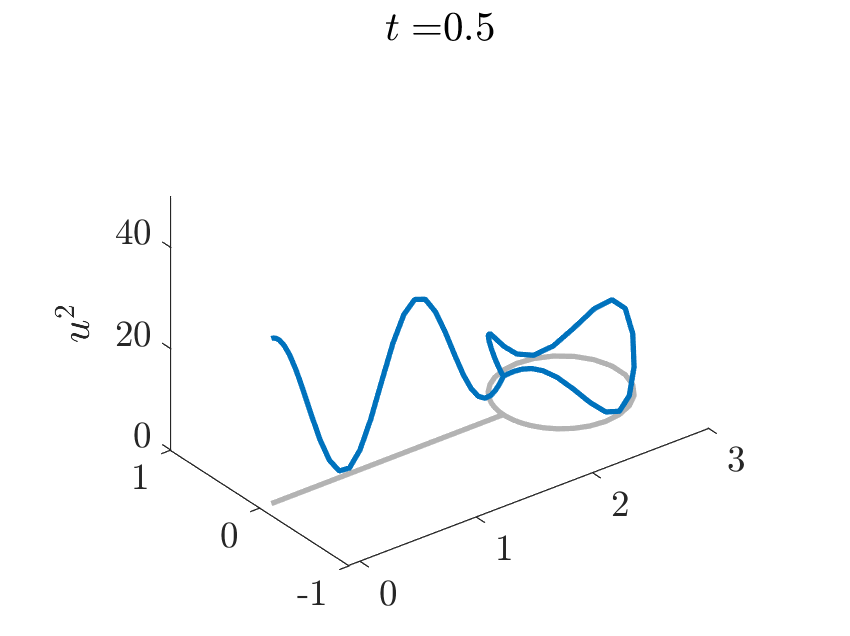

n = size(u,2);
scale = floor(n/100);
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-0.1 3 -1 1 0 50])
    daspect([1 1 25])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$u^2$')
    pause(.0000000001)
end

## Error Analysis

Compare our numerical solution to the analytical one. 

uana = @(t) exp(1i*lambda1*t)*lambda1.*evec(:,3)+exp(1i*lambda2*t)*lambda2.*evec(:,5);

error = zeros(1,size(u,2));
for i=1:size(u,2)
    error(i) = max(uana(t(i)) - u(:,i));
end

disp('The error when comparing the numerical and analytical solutions is:')

The error when comparing the numerical and analytical solutions is:


disp(abs(max(error)))

   1.5914e-06



We also check for conservation of energy and mass.

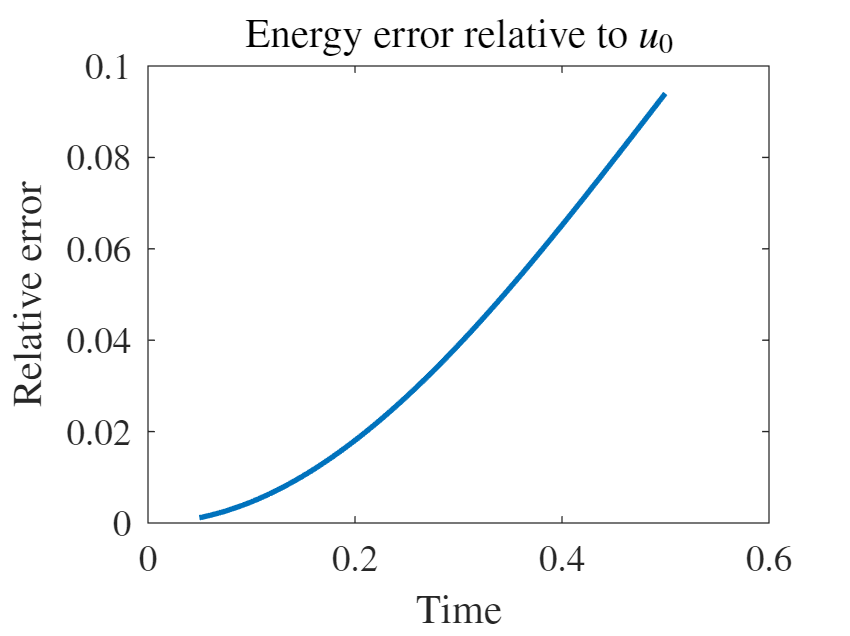

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
u0energy = 0.5*Phi.dot( A*u(:,1) , conj(u(:,1)) );
u0mass = Phi.dot(u(:,1),conj(u(:,1)));

for i=1:floor(n/scale)
    ui = u(:,scale*i);
    energyDiff(i) = abs( (0.5*Phi.dot(A*ui,conj(ui)) - u0energy) / u0energy );
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    tplot(i) = t(scale*i);
end

disp('')
plot(tplot,energyDiff)
title('Energy error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

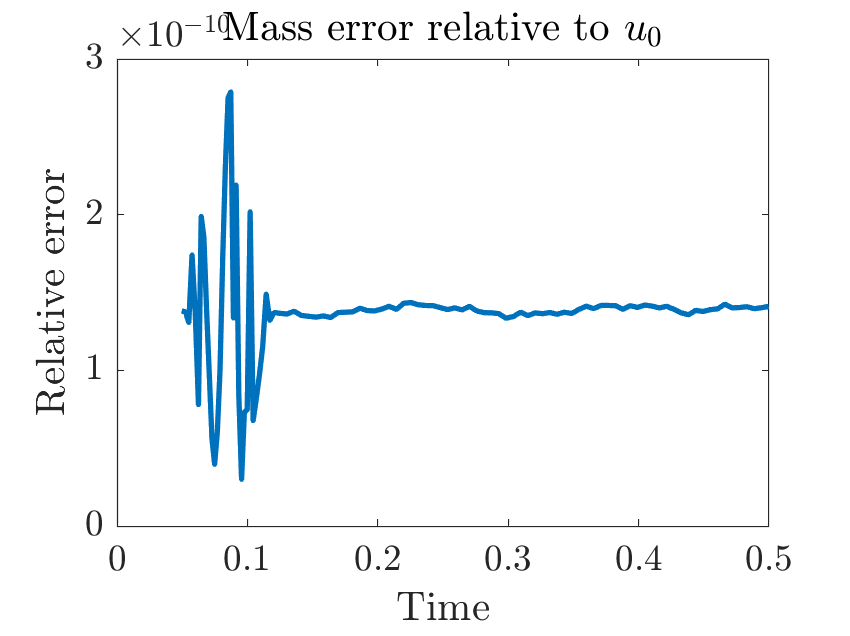

figure
plot(tplot,massDiff)
title('Mass error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

Analyzes the rate of convergence for this method

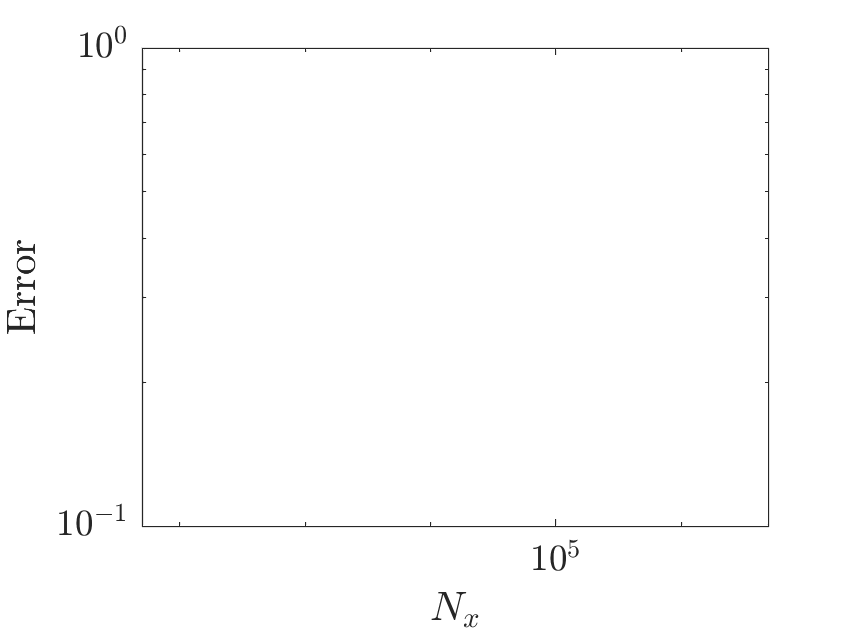

% conv = zeros(6,2);
% for j=1:6
%     deltat = 10^(-(j+1));
%     [u,t] = Phi.timeEvolveDH(f,u0,tend);
%     
%     error = zeros(1,size(u,2));
%     for i=1:size(u,2)/scale
%         error(i) = max(uana(t(i)) - u(:,i));
%     end
%     
%     conv(j,:) = [tend/deltat,abs(max(error))];
% end
% 
% loglog(conv(:,1),conv(:,2))
% xlabel('$N_t$')
    % ylabel('Error')

Spatial analysis

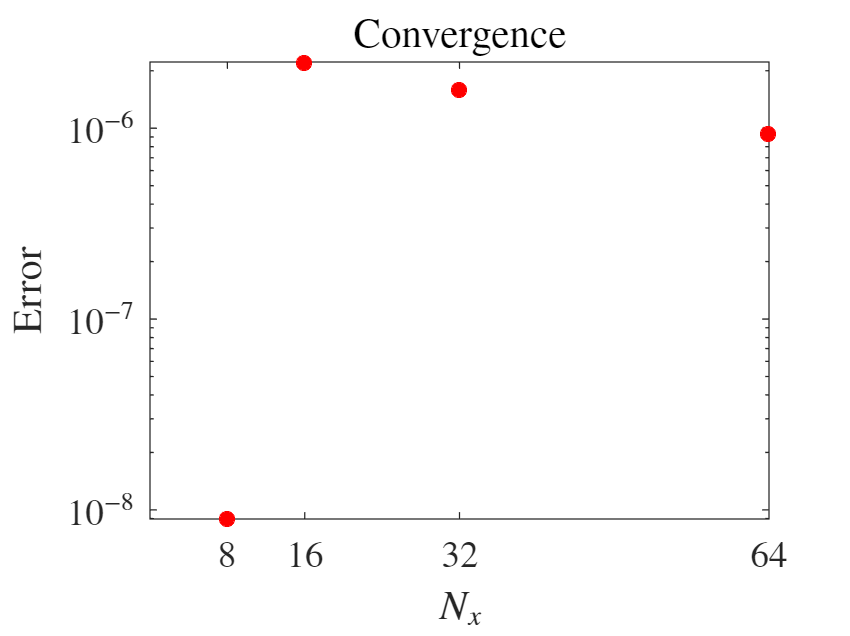

conv = zeros(4,2);
for j=1:4
    nx = 2^(j+2);
    Phi = quantumGraphFromTemplate('multibell','discretization','Chebyshev','nX',nx,'nbells',1);
    A = Phi.laplacianMatrix;
    f = @(t,z) 1i * A*z;

    [evec,eval] = Phi.eigs(8);
    lambda1 = eval(3);
    lambda2 = eval(5);
    u0 = lambda1.*evec(:,3)+lambda2.*evec(:,5);
    tend = 1;
    [t,u] = Phi.timeEvolveDH(f,u0,tend);      % Calculation for nx = 64 took 1hr 25min

    uana = @(t) exp(1i*lambda1*t)*lambda1.*evec(:,3)+exp(1i*lambda2*t)*lambda2.*evec(:,5);
    maxdiff = zeros(1,size(u,2));
    for i=1:size(u,2)
        maxdiff(i) = max(uana(t(i)) - u(:,i));
    end
    conv(j,:) = [nx,max(abs(maxdiff))];
end

plot(conv(:,1),conv(:,2),'r*')
set(gca, 'YScale', 'log')
xticks([conv(:,1)])
title('Convergence')
xlabel('$N_x$')
ylabel('Error')